# Making Plots

There are lots of ways to plot stuff in Matlab.  This live script will go over the basics of 2D line and scatter plots, as well as plotting a function.

## Some preliminaries

The most robust plotting in Matlab, be it 2D or 3D, is done by graphing numerical values.  Not functions.  This may seem odd if you've used to Mathcad.  The graphing in Matlab is like Excel: you graph numbers.

A common engineering problem is to plot the image of a function.  So we need to define the range of the plot ourselves.  For example if we want to plot $x^2$ from $x \in [-3,2]$ that could be done by first defining the range and number of points to plot

x = linspace(-3 , 2, 100);

Then we can build the function, and its image

f = @(x) x.^2;
y = f(x);

Yes, that's extra steps for a simple example like this, but for more complicated situations this pattern is handy.

## Plot: basics

The best-est plotting command in Matlab is `plot`.  The first time its called, it'll make a figure window and put line plot up on it.

plot(x,y)

 When we use a script or function, instead of a live script the behavior is a little different.  Each additional call to plot will overwrite the plot, unless we tell Matlab to just keep adding them by using `hold on`.

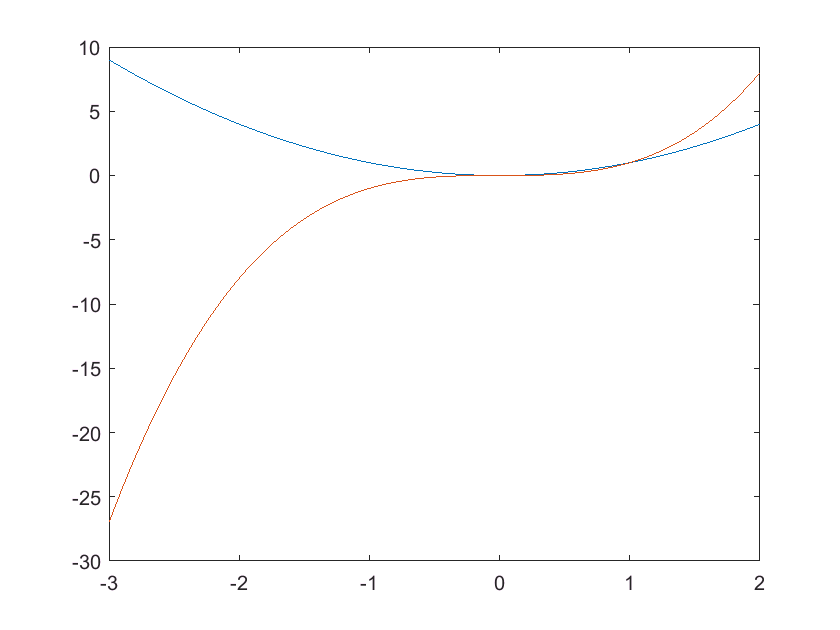

hold on
plot(x,x.^3)

If we want a second figure, when we need to use the `figure` command.

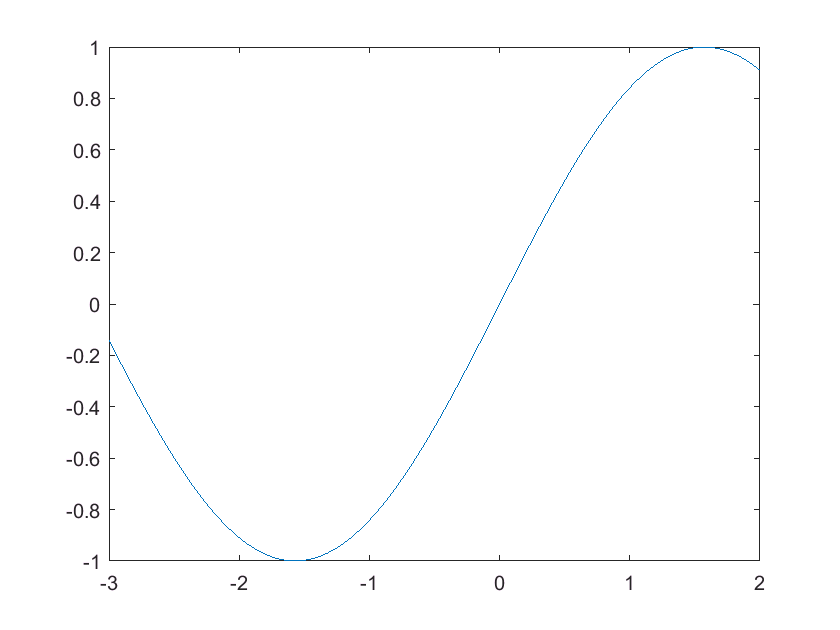

figure
plot( x, sin(x) )

## Plot: options

Plot has a million options, things like line color, line size, line style (solid, dashed, etc), markers, axes scaling, axes labels, tick marks, grid lines, legends, etc. are all up for grabs.   

**Best Practice**: 

- Plots must always have labels (with units unless dimensionless).

- If you'll be trying to read the graph later for specific values, put on grid lines and ensure you have enough (but not too many) ticks.

- Don't graph regions you don't care about.  Just because you integrated 100 seconds of an ode, that doesn't mean the plot of the response is meaningful.  Plot what is important, and nothing more.  

Example of a plot with a bunch of options: I want to find a good guess to solve 


$$\cos\left( \beta L \right) \cosh\left(\beta L\right)  = -1$$


This shows up in beam vibration problems.  So I'll make a graph

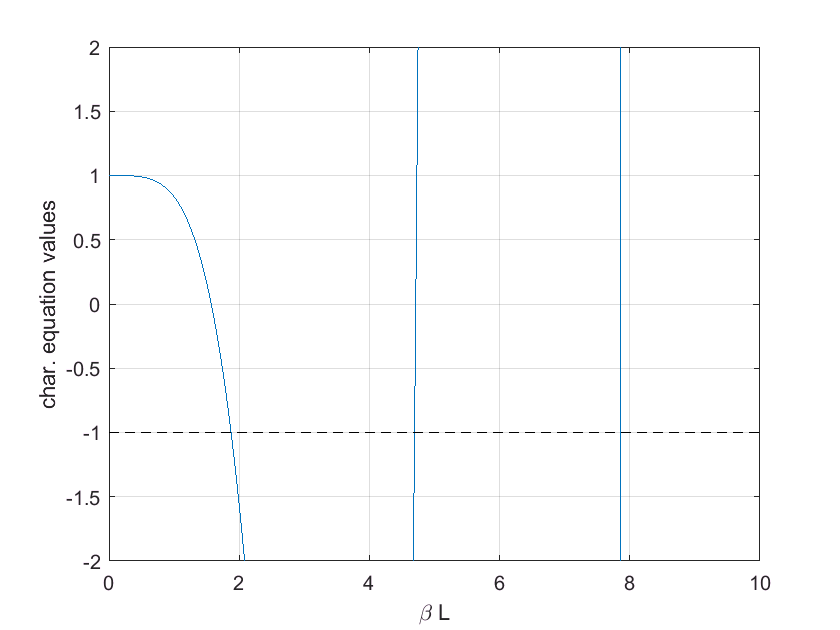

betaL = linspace(0,10,300);
f1 = cos(betaL).*cosh(betaL);

figure
plot(betaL, f1)
hold on
plot( [0, betaL(end)], [-1,-1], 'k--' )
xlabel('\beta L')
ylabel('char. equation values')
ylim([ -2, 2])
grid on

Notice how I zoomed in to see the value I care about.  Now I can make good guess

f = @(x) cos(x).*cosh(x) + 1;

x1 = 1.9;
fzero(f, x1)

ans = 1.8751


x2 = 4.5;
fzero(f, x2)

ans = 4.6941


x3 = 8;
fzero(f, x3)

ans = 7.8548

## Line options

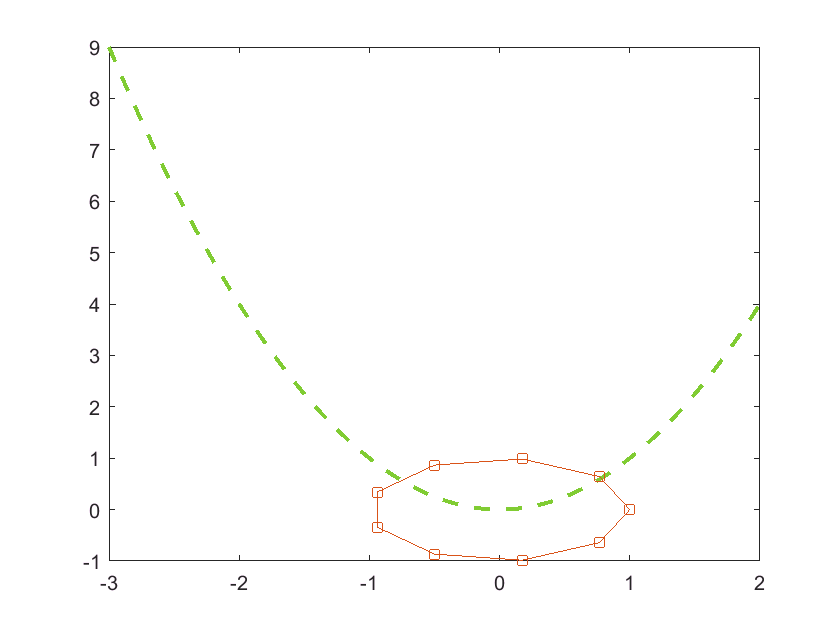

figure
plot( x, x.^2, 'color', [0.5, 0.8, 0.2], 'LineWidth', 2, 'LineStyle', '--')
hold on

t = linspace(0, 2*pi, 10);
plot( cos(t), sin(t), '-s');


% set(gca, 'DataAspectRatio', [1,1,1]);

## Multiple y-scales

Sometimes you need to plot two (or more) lines with vary different vertical scaling.  To do this, we can use the `yyaxis` command.

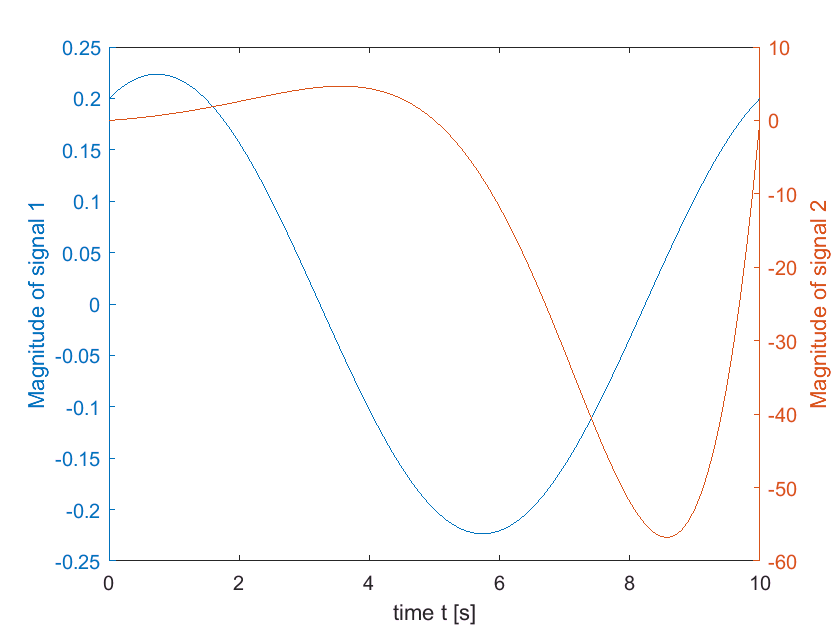

t = linspace(0,10,100);
y1 = 0.1*sin(20*pi*t) + 0.2*cos(20*pi*t);
y2 = sin(20*pi*t).*exp(0.5*t);

figure

yyaxis left
plot(t, y1)
ylabel('Magnitude of signal 1')

yyaxis right
plot(t, y2)

xlabel('time t [s]')
ylabel('Magnitude of signal 2')

## Subplots

If we have plots that are linked together, it may be useful to plot the graphs on the same figure. `subplot` has lots of various options.  As an example, I'll make two plots (one above the other), so that's a grid of 2x1

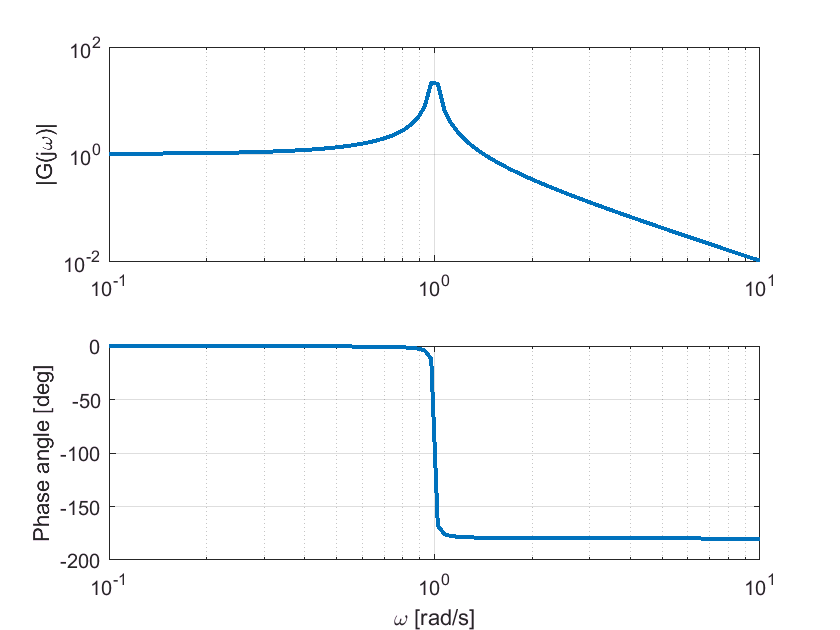

w = logspace(-1,1,100);
G = tf(1,[1,0.01, 1]);
Gw = squeeze( freqresp( G, w) ); 

figure
% grid 2 by 1, plot number 1
subplot(2,1,1)
loglog(w, abs(Gw), 'LineWidth', 2 )
grid on
ylabel('|G(j\omega)|');

% grid 2 by 1, plot number 2
subplot(2,1,2)
semilogx(w, angle(Gw)*180/pi , 'LineWidth', 2 )
grid on
ylabel('Phase angle [deg]')
xlabel('\omega [rad/s]')

## Plotting a function directly

Matlab has the tools to make a quick and easy plot of a function directly.  This is the `fplot` command.  

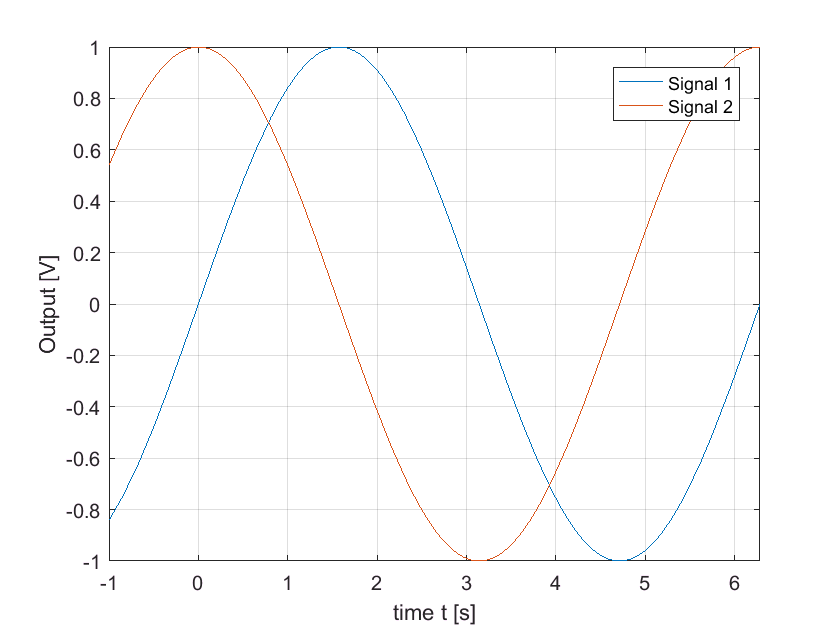

figure
fplot( @(x) sin(x), [-1,2*pi])
hold on
fplot( @(x) cos(x), [-1,2*pi])
xlabel('time t [s]')
ylabel('Output [V]')
grid on

legend('Signal 1', 'Signal 2')